# Lecture 5 notes

Welcome to another lecture on EEG data analysis, where, once again, we will be going through some MATLAB basics. So far, we have covered some of the most common data types in MATLAB and how everything in MATLAB is an array upon which we can perform various operations. We have also covered the three types of control flow; sequential, conditional, and loop control. Below are some code examples of what we can do with what we have covered so far, which you can use for revision or just to play around with:

myMatrix = [1 4 5; -2 3 0] % 2x3 numerical array (matrix)
myOtherMatrix = [5 -3; sin(0) 5+5; pi 3^2] % 3x2 numerical array (matrix)

% We can perform element-wise operations
myThirdMatrix = myMatrix .*2 % double the elements of myMatrix

% We can find one or more specific elements using indexing
idx = myThirdMatrix(:,2) % assign 2nd column of myThirdMatrix to idx

% We can replace certain values in a similar manner
myMatrix(:,3) = [0 1] % replace third column (all rows) with 0 and 1

% We can even replace elements outside the bounds of our current matrix
myMatrix(:,end+1) = [5 5] % replace 4th column (end+1=3+1=4) with 5 and 5.

% We can use built-in functions to perform calculations on our arrays
meanMyMatrix = mean(myMatrix) % Returns column-wise means

% We can specify conditions for whether or not to run code
if size(myMatrix,1) < 2 % if myMatrix has less than (relational operator) 2 rows
    minMyMatrix = min(myMatrix)
else
    maxMyMatrix = max(myMatrix)
end

% We can use loops (here a nested for loop for demonstration) to repeat code
for i = 1:5 
    for j = 1:5
      myLoopMatrix(i,j) = 0 + j; % the "inner" loop runs 5 times for i=1,
    end                          % then 5 times for i=2, etc. up to i=5.
end

% We can combine ("concatenate") matrices
combinedMatrix = [myOtherMatrix myThirdMatrix'] % here I transposed myThirdMatrix

% We can combine strings into longer strings in a similar manner, and we
% can convert numbers to strings using the num2str function
x = randi(100) % random integer between 1 and 100
myString = ['Your random number is ' num2str(x) ', a fine number, indeed.']

% Finally, we can put some of the pieces together. This code creates a new
% folder called new_folder (if one does not already exist). It then saves
% the variable myString to that folder.
currentFolder = pwd;
if ~exist('new_folder', 'dir')
    mkdir('new_folder')
end

newFold = [currentFolder filesep 'new_folder'];
cd(newFold)
save('myString.mat', 'myString')
cd(currentFolder)

## Functions

MATLAB contains a large number of built-in functions, a few of which we have already started using. Additionally, EEGLAB and ERPLAB also contain a large number of functions created specifically to process EEG data. It may sometimes be beneficial to define (create) one's own functions; however, our primary purpose in this lecture will be to understand better how to use existing functions in MATLAB.

Let us start by navigating to the **Home** tab and clicking **New** > **Function**, which opens up a new script, where MATLAB has been kind enough to provide us with a template for creating a function:

MATLAB suggests two input and output arguments by default, but you can change that (see below). Below is the general structure of a function:

When we define a function, we write one or more lines of code that take a specified input and do something with it. For example, the `mean` function takes a vector of numbers as input. It calculates the average and returns the result as the output. 

The first function we will write will take as input a variable, and return as output the (element-wise) square of that variable:

We can call the output (`theSquare`) whatever we want, and the same goes for the input (`x`):

#### Saving the function

However, to use the function, we need to save the file and name it with the same name as our `functionName`. Use names that make sense when naming your function. You should also make the function name unique, i.e. you do not want to create a function called `mean` since such a function already exists in MATLAB. Having two or more functions with the same name (called shadowing) increases the risk of errors. You can use the built-in function `which` to locate existing functions if you are unsure if the name you want to use is taken. For example:

which('mean') % shows the location of the mean function

which('ThisDoesNotExist') % not found, no problem using this name

You can also open up a function using the `edit` command:

edit mean

In our case, we save our function as `computeSquare.m`.

To call our `computeSquare` function, try typing the following in the Command Window or in a script (not the same as the function is in):

myNumber = computeSquare(4)

Hopefully, everything works and the function returns 16. We can try it again:

myNumber = computeSquare(myNumber) % myNumber squared

An important aspect of functions is that everything that happens within a function is hidden from the main Workspace; only the output of a function is saved in the Workspace. 

If we look at the template function provided by MATLAB again, you will notice two lines of comments. These comments are used to provide an explanation of your function, for example:

Try the following command in the Command Window after adding the comments above:

help computeSquare

We can see that our comments actually created some help text for our function. We have now created our first function:

clear;clc;
myMatrix = randi(5,3) % create 3x3 matrix of random integers between 1 and 5
myMatrixSquared = computeSquare(myMatrix) % Square each element

Next, we will define another function, this time with one input and two output arguments. First, however, we will take a look at multiple outputs.  Previously, we have learned how to assign the output of a function to a variable, such as:

myVariable = randi(100,5,3) % 5x3 matrix
meanX = mean(myVariable) % function output assigned to meanX
minX = min(myVariable) % function output assigned to minX

Some functions, however, give multiple outputs. Take the `min` function, for example:

min(myVariable) % returns the minimum value of every column
[minMyVar, idxMyVar] = min(myVariable)  % also returns the index of the minimum values

In the code above, the random matrix ***myVariable*** is first entered into the `min` function, and we receive the minimum value as our output. However, the min function can also provide additional outputs. Above, we declare two variables, ***minMyVar*** and ***idxMyVar***. As usual, ***minMyVar*** is the min value of every column. The `min` function also returns the index of the minimum value as another output, here assigned to ***idxMyVar***.

Another example is the `size` function:

[m, n] = size(myVariable) % m: number of rows, n: number of columns

Now, let us define a new function. We will create a function that calculates the mean and standard deviation of an input variable (using built-in functions). The function is called `stat`, so we name our script file `stat.m`.

Let us start from the top. The first line indicates that our function returns 2 outputs `[m, sd]`, it is named `stat`, and we take one input x`.` Next, we have added some help text in the form of comments. Inside our function are the calculations that we perform on the input value. Here, we have added a conditional statement, where we use `nargin`, which represents the number of input arguments (`help nargin`). While not strictly necessary, here we have chosen to add an error message if the user provides 0 inputs, else calculating the mean and standard deviation if the user provides 1 input.

myVariable = randi(100,5,3); % 5x3 matrix
[meanMyVar, sdMyVar] = stat(myVariable)

stat() % no input arguments

### Finding new functions

When you are googling your heart out trying to solve some problem using MATLAB, you will likely come across [MATLAB answers](https://se.mathworks.com/matlabcentral/answers/index). Here, you can ask questions yourself or read other users' questions (see e.g. [FAQ](https://se.mathworks.com/matlabcentral/answers/faqs/?s_tid=ta_ans_quicklinks_faqs)). These forums are part of the official MathWorks homesite. It is not uncommon for the staff at MathWorks to answer questions. For example, here is a [forum post](https://se.mathworks.com/matlabcentral/answers/2813-best-file-exchange-ever) where users vote on their favourie [File exchange](https://se.mathworks.com/matlabcentral/fileexchange/), which is a place where users can share their MATLAB code. 

In the above forum post, someone mentioned a function called [keep](https://se.mathworks.com/matlabcentral/fileexchange/181-keep), which is supposedly similar to the `clear` command, except it keeps variables we choose and deletes the rest. If we would like, we could download and unzip this function into our Current Folder, where we could then try it out ourselves. We can open it up like a regular script (or run `edit` `keep`), and if we run the following code:

x = 5
y = 10
z = 9
keep('x') % function from the MATLAB file exchange

The function will indeed keep ***x*** for us in the Workspace and clear the rest. Note that in the function above, I specified the input argument as a string (`'x'` instead of ***x***), something which is very common in MATLAB functions.

## Plotting

Matlab is a powerful tool for data visualization. A basic function with which you can plot your data is the `plot` function, which produces line graphs of one or two variables. To see how `plot` works, we will first create three variables, ***x***, ***y***, and ***z***:

clear;clc; % clear Command Window and Workspace
x = 0:0.01:2*pi; % vector from 0 to 2*pi
y = sin(x); % sine of x in radans
z = cos(x); % cosine of x in radans

***x*** is an evenly spaced vector between $0$ and $2\pi$ (6.28) with steps of 0.01. We then apply the sine and cosine functions when we create ***y*** and ***z***. In case you have forgotten trigonometry since high school, these functions will produce a "circular" pattern, going up and down between -1 and 1 (2*pi is one turn of a circle).

We can use the `plot` function to produce line graphs of one or two variables:

figure % open a figure
plot(y) % plots the elements of y against the index of the elements of y (1:629)
figure % open new figure
plot(x,y) % plots y (on y-axis) versus x (on x axis)

- Do you notice the difference between the two plots (hint: x-axis)?

We can use the command `close` to close down the current figure, or `clear all` to close all figures (similar to `clear` for Workspace):

close all

We can use the `hold on` and `hold off` commands to add several lines to the same plot:

figure(1) % create figure 1
plot(x,y)
hold on
plot(x,z)
hold off

If our y-axis is a matrix instead of a vector, `plot` will treat each row as a separate data series to plot, and we get the same result as above:

yz = [y;z]; % combine y and z into 2x629 matrix yz. We "put them on top of" each other.
plot(x,yz)

You can use additional inputs into the `plot` function to specify color, line styles, and markers. Note that you need to use 'characters' for these inputs. The image below shows commands for different plot syles, taken from [this link](https://www.mathworks.com/help/releases/R2019a/pdf_doc/matlab/getstart.pdf).

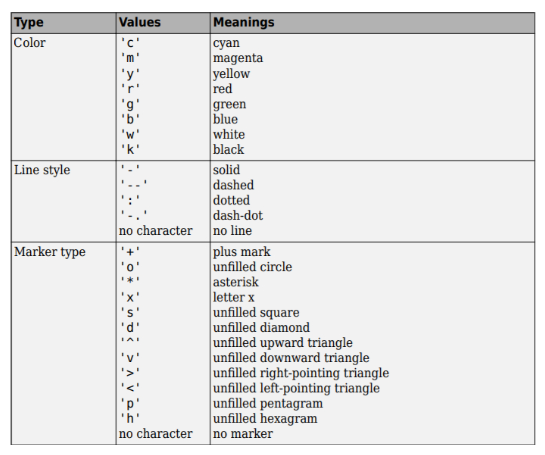

Let us look at the plot of y aganist x. To change the color to red, we can use the extra `'r'` input:

plot(x,y,'r')

You can also change the line style using an optional argument. Below, we change the line style to a dotted line:

plot(x,y,':')

Individual data points are not marked on the line plot by default. We can mark individual points by changing the marker style. Below we mark them as circles, although this is hard to see when we have so many data points close to each other:

plot(x,y,'o')

You can combine plot options to specify color, marker style, and line style together. Generally, the order doesn't matter, so the following two commands produce the same plot using a red dotted line:

close all
figure(1)
plot(x,y,'r:')
figure(2)
plot(x,y,':r')

- How would you plot ***z*** against ***x*** as a black dashed line?

Next, we can add labels to a graph using so-called "annotation functions", such as `xlabel` and `ylabel`:

xlabel('Text Label for X-Axis')
ylab = 'Text Label for Y-Axis' % we can also create a string
ylabel(ylab) % and put the string into the function

We can also add a title using the `title` function:

title('Plot of the Sine Function')

As you can see, we build our figure up by using various commands. Below, we create a figure from scratch, with both ***y*** and ***z***:

% Generate waves again:
close all
clear
x = 0:0.01:2*pi;
y = sin(x); % sine of x in radans
z = cos(x); % cosine of x in radans

figure(1)
plot(x,y,'r') % red line
hold on % keep working on this figure
plot(x,z,'k') % black line

xlabel('Time (s)') % set the x label. There are more inputs, e.g. 'FontSize'
ylabel('Amplitude (\muV)') % side note: \mu creates the greek letter mu (LaTex syntax)
title('Sine and Cosine Waves Pretending to be EEG Data') % add a title to the graph


Finally, let us add a legend so we can tell which wave is which using the `legend` function. The input arguments to `legend` should have the same order as the order in which the lines were drawn above (first we plotted y against x and then z against x):

legend('Sine', 'Cosine') % Let us just called them Sine and Cosine

By default, MATLAB puts the legend in the top-right corner. In this case, the legend is kind of in the way. The `legend` function also accepts two optional input arguments: the keyword `'Location'` and a text description of the location, which is given by compass points, such as `'north'` or `'southwest'.` Let us put the legend in the bottom-left corner, which would mean southwest:

legend('Sine', 'Cosine', 'Location', 'southwest')
hold off

Finally, in the **Figure** window, you can click **File** > **Save** **As** to save your image.

- One final remark. I recommend playing around with creating various kinds of plots when you have the time (e.g. different variables, different colors, labels, and so on). Besides learning to create figures, it is a good way to get used to using multiple input arguments into functions (see e.g. legend above). For example, below is an image of some code using an EEGLAB function called pop_clean_rawdata, which can be used to identify electrodes with high noise levels in an EEG dataset.

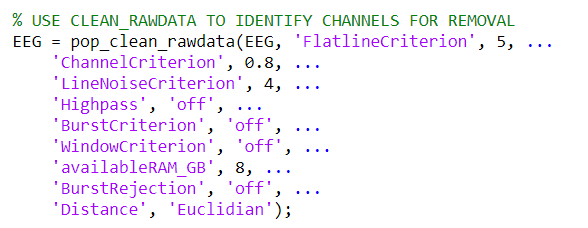

The function takes several different input arguments (the three dots can be used when writing a function over multiple lines). This and similar functions are commonly used when creating EEG analysis scripts, but more on that later.

**Summary**

- Functions are separate scripts that perform some specific task. A function takes one or more input arguments (e.g. an array) and produces on or more outputs (e.g. the mean of every column). In MATLAB, functions are defined in separate files. The name of the file and of the function should be the same.

- When creating plots in MATLAB, we build our custom-made figures using various built-in commands and annotation functions, such as `plot`, `xlabel`, `title`, and `legend`. The `hold on` and `hold off` commands are also very useful for this.